clc;
clear;
close all;
addpath('../Definition'); 
addpath('../Kinematics');


%% 1. 参数定义
run('../Definition/set_parameter.m');

%% 2. 关节角范围
theta_lim = [0, 180];
phi_lim   = [0, 90];

%% 3. 采样网格
theta_vec = linspace(theta_lim(1), theta_lim(2), 100);
phi_vec   = linspace(phi_lim(1),   phi_lim(2),   100);

[Theta, Phi] = meshgrid(theta_vec, phi_vec);

% 注意：这里要初始化为 NaN，而不是 0
x_G = nan(size(Theta));
y_G = nan(size(Theta));

%% 4. 遍历所有采样点
for i = 1:numel(Theta)

    th = Theta(i); 
    ph = Phi(i);

    if check_interference(th, ph, params)

        [~, ~, ~, ~, ~, ~, ~, ~, ~, ~, x_G(i), y_G(i)] = ...
            modelingfx(th, ph, params);

    end
end

%% 5. 提取有效工作空间点
id_ok = ~isnan(x_G) & ~isnan(y_G);

x_ws = x_G(id_ok);
y_ws = y_G(id_ok);

% 去掉重复点，避免 alphaShape 计算量过大
P = unique([x_ws(:), y_ws(:)], 'rows');

x_ws = P(:,1);
y_ws = P(:,2);

%% 6. 用 alphaShape 表示工作空间边界

shp0 = alphaShape(x_ws, y_ws);

% 自动寻找一个使工作空间连通的 alpha
alpha_ref = criticalAlpha(shp0, 'one-region');

% 可根据实际情况调整，例如 0.8、1.0、1.2 倍
alpha = alpha_ref;

shp = alphaShape(x_ws, y_ws, alpha);

workspace_area = area(shp);
fprintf('工作空间面积约为：%.4f mm^2\n', workspace_area);

工作空间面积约为：21664.9646 mm^2




%% 7. 在工作空间内搜索最大轴对齐矩形

% 网格数量，越大越精确，但计算越慢
Nx = 500;
Ny = 500;

x_min = min(x_ws);
x_max = max(x_ws);
y_min = min(y_ws);
y_max = max(y_ws);

x_edges = linspace(x_min, x_max, Nx + 1);
y_edges = linspace(y_min, y_max, Ny + 1);

dx = x_edges(2) - x_edges(1);
dy = y_edges(2) - y_edges(1);

% 网格单元中心
x_centers = 0.5 * (x_edges(1:end-1) + x_edges(2:end));
y_centers = 0.5 * (y_edges(1:end-1) + y_edges(2:end));

[Xc, Yc] = meshgrid(x_centers, y_centers);

% 为了更保守，要求单元中心和四个角点都在工作空间内
[XL, YB] = meshgrid(x_edges(1:end-1), y_edges(1:end-1));
[XR, YT] = meshgrid(x_edges(2:end),   y_edges(2:end));

inside_center = inShape(shp, Xc, Yc);

inside_lb = inShape(shp, XL, YB);
inside_rb = inShape(shp, XR, YB);
inside_lt = inShape(shp, XL, YT);
inside_rt = inShape(shp, XR, YT);

inside_mask = inside_center & inside_lb & inside_rb & inside_lt & inside_rt;

% 在二值矩阵 inside_mask 中寻找最大全 true 矩形
[rect_area, r1, r2, c1, c2] = largestRectangleInMask(inside_mask, dx, dy);

rect_x1 = x_edges(c1);
rect_x2 = x_edges(c2 + 1);
rect_y1 = y_edges(r1);
rect_y2 = y_edges(r2 + 1);

rect_width  = rect_x2 - rect_x1;
rect_height = rect_y2 - rect_y1;

fprintf('最大矩形面积约为：%.4f mm^2\n', rect_area);

最大矩形面积约为：9837.9750 mm^2


fprintf('矩形宽度：%.4f mm，高度：%.4f mm\n', rect_width, rect_height);

矩形宽度：172.8200 mm，高度：56.9261 mm


fprintf('矩形范围：x = [%.4f, %.4f], y = [%.4f, %.4f]\n', ...
    rect_x1, rect_x2, rect_y1, rect_y2);

矩形范围：x = [-108.1331, 64.6869], y = [134.2803, 191.2065]


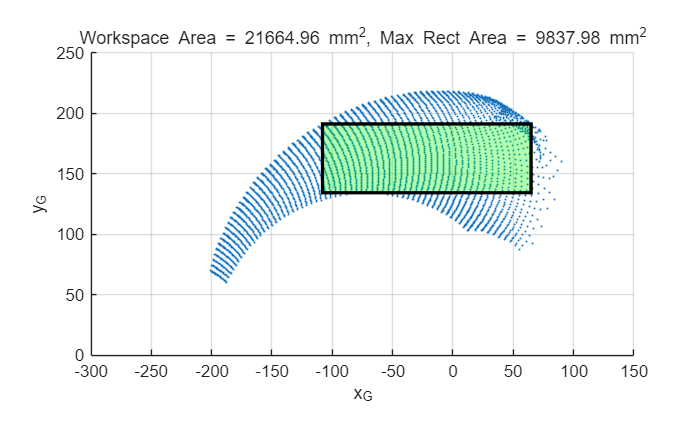

fprintf('面积比约为：%.4f \n', rect_area / workspace_area);

%% 8. 绘制工作空间散点、边界和最大矩形

figure;
hold on;

% 工作空间散点
plot(x_ws, y_ws, '.', 'MarkerSize', 2);

% alphaShape 边界
% plot(shp, ...
%     'FaceColor', [0.3 0.7 1.0], ...
%     'FaceAlpha', 0.20, ...
%     'EdgeColor', 'r', ...
%     'LineWidth', 1.2);

% 最大矩形
rect_x = [rect_x1, rect_x2, rect_x2, rect_x1, rect_x1];
rect_y = [rect_y1, rect_y1, rect_y2, rect_y2, rect_y1];

patch(rect_x, rect_y, 'g', ...
    'FaceAlpha', 0.30, ...
    'EdgeColor', 'k', ...
    'LineWidth', 2);

axis equal;
grid on;
xlabel('x_G');
ylabel('y_G');

title(sprintf('Workspace Area = %.2f mm^2, Max Rect Area = %.2f mm^2', ...
    workspace_area, rect_area));

xlim([-300 150]);
ylim([0 250]);


% saveFigIEEE('1');
